# GORILLA plotting tutorial

With the plotting option of GORILLA it is possible to compute and plot the orbit of a particle in a toroidal magnetic fusion device. For the visualization of the orbit, Poincare plots are used. The program also computes various constants of motion to check how the obtained results behave with respect to numerical accuracy.  

This tutorial guides through diffrent input options of the code and shows a way how to execute the code with MATLAB. 

## Initialization

First, the MATLAB code needs to know where to find the used files. Therefore, it is necessary to specify some paths. If the folder of GORILLA is unchanged and the current folder of MATLAB is the folder of this MATLAB script the default values should work. 

First, the path of the MATLAB script must be specified:

path_script=pwd;
%default: path_script=pwd;

The path of the main folder of the GORILLA code:

path_main=[path_script,'/../'];
%default: path_main=[path_script,'/../'];

The path where the FORTRAN code should be executed:

mkdir(path_main,'EXAMPLES/MATLAB_RUN/plot_poincare');
path_RUN=[path_main,'/EXAMPLES/MATLAB_RUN/plot_poincare'];
%default path_RUN=[path_main,'/EXAMPLES/plot_poincare'];
cd(path_RUN);
! rm -r ../plot_poincare/*

rm: cannot remove '../plot_poincare/*': No such file or directory


In the INPUT folder the input files for the GORILLA code are already prepared. All input variables have a default value. These input files will be loaded into the MATLAB script later on.

path_inp_files=[path_main,'/INPUT'];
%default path_inp_files=[path_main,'/INPUT'];
addpath(path_inp_files);

Some parts of this MATLAB Live Script are outsourced to functions. Those functions are stored in a separate folder.

path_functions=[path_main,'/MATLAB/functions'];
%default path_functions=[path_main,'/matlab_test_cases/functions'];
addpath(path_functions);

The created files during this run will be stored in a separate folder. The code will create a new folder if the folder does not exist.

name_folder='data_plots/plot_poincare';
mkdir(path_script,name_folder);
path_data_plots=[path_script,'/',name_folder];

## Input variables

The GORILLA code requires some input files. All possible options for the code can be set in these files. In the INPUT folder, there are already default input files. In these files one can also find short explanations for ervery variable. In this script all input files will be loaded. The function InputFile creates an object for every input file.

gorilla = InputFile([path_inp_files,'/gorilla.inp']);
gorilla_plot = InputFile([path_inp_files,'/gorilla_plot.inp']);
tetra_grid = InputFile([path_inp_files,'/tetra_grid.inp']);

With the read methode all input variables from the input files are loaded into the script. With that, it is possible to change all settings within this script. If a varibale is not changed inside this script, than the program uses the default value out of the INPUT folder.

gorilla.read();
gorilla_plot.read();
tetra_grid.read();

## Input file gorilla.inp

Electrostatic potential

Electrostatic potential within the plasma volume in Gaussian units: 

The potential is realised in GORILLA as a rescaling of the toroidal flux by eps_Phi. This results in surfaces of equal potential coinciding with the flux surfaces and an electric field perpendicular to them.

gorilla.GORILLANML.eps_Phi = 0;

Coordinate system

    1 ... (R,phi,Z) cylindrical coordinate system

    2 ... (s,theta,phi) symmetry flux coordinate system 

gorilla.GORILLANML.coord_system = 2;

 Particle species

    1 ... electron

    2 ... deuterium ion

    3 ... alpha particle

gorilla.GORILLANML.ispecies = 2;

 Switch for initial periodic coordinate particle re-location (modulo operation)

    true ... Particles are re-located at initialization in the case of a periodic coordinate, if they are outside the computation domain.

    false .. Particles are not re-located at initialization (This might lead to error if particles are outside the computation domain)

gorilla.GORILLANML.boole_periodic_relocation = true;

 Gorilla pusher options

    1 ... numerical RK pusher

    2 ... polynomial pusher

gorilla.GORILLANML.ipusher = 2;

Numerical pusher options

    accuracy for integration step:

        false ... RK4

        true ... adaptive ODE45

gorilla.GORILLANML.boole_pusher_ode45 = false;

    ODE45 relative accuracy (pusher_orbit)

gorilla.GORILLANML.rel_err_ode45 = 1*10-8;

    Physical time - orbit parameter relation

        false ... dt_dtau is a linear function of position in each tetrahedron

        true ... dt_dtau is a constant averaged quantity in each tetrahedron

gorilla.GORILLANML.boole_dt_dtau = true;

    Precomputation for Newton iterations

        false ... Compute coefficients for 2nd order polynomial solution (Newton velocity and acceleration) in each tetrahedron (dzdtau) without precomputation

        true ... Use precomputation of coefficients for 2nd order polynomial solution (Newton velocity and acceleration)

gorilla.GORILLANML.boole_newton_precalc = false;

Polynomial pusher options

    Polynomial order for orbit pusher

gorilla.GORILLANML.poly_order = 4;

Time tracing options

    1 ... Time tracing in 0th order approximation: dt / dtau = const. in each tetrahedral cell

    2 ... (Correct) Hamiltonian time tracing in adequate polynomial order

           Dependencies: ipusher must be 2 (Polynomial pusher)

gorilla.GORILLANML.i_time_tracing_option = 1;

    Settings for precomputation of coefficients

        0 ... No precomputation: All coefficients are computed on the fly (power of matrices)

        1 ... Precomputation of coefficients and factorization of powers of perpinv

        2 ... Same as 1 but with further precomputation of operatorb in b

        3 ... Extended precomputation of coefficients for constant perpinv

        (Precomputation is done for each tetrahedron for constant perpinv) NOT IMPLEMENTED YET

gorilla.GORILLANML.i_precomp = 0;

    Face prediction with 2nd order polynomial

        true ... Face guessing algorithm is used

        false ... NOT used

gorilla.GORILLANML.boole_guess = true;

 Processing of particle handover to tetrahedron neighbour

    1 ... Processing with special treatment of periodic boundaries and manipulation of periodic position values

    2 ... Position exchange via Cartesian variables (skew_coordinates) - Necessary precomputation is included

gorilla.GORILLANML.handover_processing_kind = 1;

Multiple options to manipulate the axisymmetric electromagnetic field (Tokamak) with noise

    Add axisymmetric random noise (\xi = 0 ... 1) to the co-variant component of the vector potential $A_k$

    $A_k = A_k (1+\epsilon_A \xi)$ 

gorilla.GORILLANML.boole_axi_noise_vector_pot = false;

    Relative Magnitude of axisymmetric random noise $\epsilon_A$ of vector potential

gorilla.GORILLANML.axi_noise_eps_A = 0.1;

    Add axisymmetric random noise to the electrostatic potential $\Phi$

    $\Phi = \Phi (1+\epsilon_\Phi \xi)$,

gorilla.GORILLANML.boole_axi_noise_elec_pot = false;

    Relative Magnitude of axisymmetric random noise $\epsilon_\Phi$ of electrostatic potential

gorilla.GORILLANML.axi_noise_eps_Phi = 0.3;

    Add non-axisymmetric random noise to the co-variant component of the vector potential $A_k$

gorilla.GORILLANML.boole_non_axi_noise_vector_pot = false;

    Relative Magnitude of non-axisymmetric random noise $\epsilon_A$ of vector potential

gorilla.GORILLANML.non_axi_noise_eps_A = 1*10-4;

Manipulation of the axisymmetric electromagnetic field (Tokamak) with helical harmonic perturbation

    Switch for helical harmonic perturbation of A_phi

        false ... no perturbation

        true ... perturbation on: A_phi = A_phi + A_phi*helical_pert_eps_Aphi * cos(m_fourier*theta +n_fourier*phi)

gorilla.GORILLANML.boole_helical_pert = false;

    Amplitude for helical harmonic perturbation

gorilla.GORILLANML.helical_pert_eps_Aphi = 0.1;

    Fourier modes of helical perturbation

 gorilla.GORILLANML.helical_pert_m_fourier = 2;
 gorilla.GORILLANML.helical_pert_n_fourier = 2;

Switches to calculate optional quantities

 gorilla.GORILLANML.boole_time_Hamiltonian = false;
 gorilla.GORILLANML.boole_gyrophase = false;

Dividing orbit integration into intermediate steps (adaptive) to reduce error made by finit polynomial

Only for ipusher = 2 (polynomial pusher)

    Switch for adaptive time step scheme

        false ... no adaptive scheme

        true ... adaptive scheme to ensure energy conservation up to specified fluctuation

gorilla.GORILLANML.boole_adaptive_time_steps = false;

    Allowed relative fluctuation of energy between entry and exit of a tetrahedron

    Must not be smaller or equal zero!

gorilla.GORILLANML.desired_delta_energy = 1.E-10;

    Maximum number of intermediate steps allowed for splitting up an orbit section

    Should not go much beyond 10000 steps.

gorilla.GORILLANML.max_n_intermediate_steps = 10000;

For strong electric field the exact, limit case of the EOM is different, which lead to additional terms 

in the approximative description in GORILLA when compared to the default case.

    Switch for including strong electric field terms

       false ... no addtional terms

       true ... including strong electric field effects

gorilla.GORILLANML.boole_strong_electric_field = false;

    Switch for saving electric field and drift to .dat-files

gorilla.GORILLANML.boole_save_electric = false;

    Filenames for strong electric field and drift velocity

gorilla.GORILLANML.filename_electric_field = 'electric_field.dat';
gorilla.GORILLANML.filename_electric_drift = 'electric_drift.dat';

### Input file tetra_grid.inp

Grid Size:

    Rectangular: nR, Field-aligned: ns

tetra_grid.TETRA_GRID_NML.n1 = 100;

    Rectangular: nphi, Field-aligned: nphi

tetra_grid.TETRA_GRID_NML.n2 = 30;

    Rectangular: nZ, Field-aligned: ntheta

tetra_grid.TETRA_GRID_NML.n3 = 30;

Grid kind:

     1 ... rectangular grid for axisymmetric EFIT data

     2 ... field-aligned grid for axisymmetric EFIT data

     3 ... field-aligned grid for non-axisymmetric VMEC

     4 ... SOLEDGE3X_EIRENE grid 

tetra_grid.TETRA_GRID_NML.grid_kind = 3;

MHD equilibrium filename

tetra_grid.TETRA_GRID_NML.g_file_filename = 'MHD_EQUILIBRIA/g_file_for_test';
tetra_grid.TETRA_GRID_NML.convex_wall_filename = 'MHD_EQUILIBRIA/convex_wall_for_test.dat';
tetra_grid.TETRA_GRID_NML.netcdf_filename = 'MHD_EQUILIBRIA/netcdf_file_for_test.nc';

MESH_SOLEDGE3X_EIRENE filename

tetra_grid.TETRA_GRID_NML.knots_SOLEDGE3X_EIRENE_filename = 'MHD_EQUILIBRIA/MESH_SOLEDGE3X_EIRENE/knots_for_test.dat';
tetra_grid.TETRA_GRID_NML.triangles_SOLEDGE3X_EIRENE_filename = 'MHD_EQUILIBRIA/MESH_SOLEDGE3X_EIRENE/triangles_for_test.dat';

Switch for selecting number of field periods automatically or manually

    true ... number of field periods is selected automatically (Tokamak = 1,       Stellarator depending on VMEC equilibrium)

    false ... number of field periods is selected manually (see below)

tetra_grid.TETRA_GRID_NML.boole_n_field_periods = true;

Number of field periods (manual)

tetra_grid.TETRA_GRID_NML.n_field_periods_manual = 1;

Symmetry Flux Coordinates Annulus (Minimal value for flux coordinates s)

tetra_grid.TETRA_GRID_NML.sfc_s_min = 0.1;

Option for $\theta$-variable being used in grid

    1 ... theta scaling in symmetry flux coordinates

    2 ... theta scaling in geometrical theta angle 

tetra_grid.TETRA_GRID_NML.theta_geom_flux = 1;

Option for $\theta$-variable origin

    true ... $\theta$-variable starts at the line between O- and X-Point

    false ... $\theta$-variable starts at the line between O-Point and intersection between O-Point-[1,0]-straight-line and separatrix

tetra_grid.TETRA_GRID_NML.theta0_at_xpoint = false;

Switch for writing object file with mesh data

tetra_grid.TETRA_GRID_NML.boole_write_mesh_obj = false;

 Filename for mesh object file in cylindrical coordintes

tetra_grid.TETRA_GRID_NML.filename_mesh_rphiz = 'mesh_rphiz.obj';

Filename for mesh object file in symmetry flux coordintes 

tetra_grid.TETRA_GRID_NML.filename_mesh_sthetaphi = 'mesh_sthetaphi.obj';

## Inputfile gorilla_plot.inp

Switch for options

    1 ... Single orbit - Starting positions and pitch for the orbit are taken from file (see below) [First Line]

    2 ... Single orbit - Starting positions and pitch for the orbit are taken from starting drift surfaces (see below)

    3 ... Multiple orbits - Starting positions and pitch for orbits are taken from file (see below) [Every Line New Starting position]

    4 ... Multiple orbits - Starting positions and pitch for orbits are taken from drift surfaces with regular spacing (see below)

gorilla_plot.GORILLA_PLOT_NML.i_orbit_options = 2;

Total individual orbit flight time for plotting

gorilla_plot.GORILLA_PLOT_NML.total_orbit_time = -1.0;

Total Energy of particle in eV

gorilla_plot.GORILLA_PLOT_NML.energy_eV_start = 3000;

Plot Poincaré cuts ($\varphi$ = 0)

    Switch for plotting Poincaré cuts at toroidal variable $\varphi$ = 0

 gorilla_plot.GORILLA_PLOT_NML.boole_poincare_phi_0 = false;

    Number of skipped (non-printed) Poincaré cuts at toroidal variable $\varphi$ = 0

 gorilla_plot.GORILLA_PLOT_NML.n_skip_phi_0 = 100;

    Filename for Poincaré cuts at toroidal variable $\varphi$ = 0 in cylindrical coordinates (R,$\varphi$,Z)

gorilla_plot.GORILLA_PLOT_NML.filename_poincare_phi_0_rphiz = 'poincare_plot_phi_0_rphiz.dat';

    Filename for Poincaré cuts at toroidal variable $\varphi$ = 0 in symmetry flux coordinates      (s,$\vartheta$,$\varphi$)

gorilla_plot.GORILLA_PLOT_NML.filename_poincare_phi_0_sthetaphi = 'poincare_plot_phi_0_sthetaphi.dat';

Plot Poincaré cuts ($v_\parallel$ = 0)

    Switch for plotting Poincaré cuts at parallel velocity $v_\parallel$ = 0

gorilla_plot.GORILLA_PLOT_NML.boole_poincare_vpar_0 = true;

    Number of skipped (non-printed) Poincaré cuts at parallel velocity $v_\parallel$ = 0

gorilla_plot.GORILLA_PLOT_NML.n_skip_vpar_0 = 1;

    Filename for Poincaré cuts at parallel velocity $v_\parallel$ = 0 in cylindrical coordinates (R,$\varphi$,Z)

gorilla_plot.GORILLA_PLOT_NML.filename_poincare_vpar_0_rphiz = 'poincare_plot_vpar_0_rphiz.dat';

    Filename for Poincaré cuts at parallel velocity $v_\parallel$ = 0 in symmetry flux coordinates (s,$\vartheta$,$\varphi$)

gorilla_plot.GORILLA_PLOT_NML.filename_poincare_vpar_0_sthetaphi = 'poincare_plot_vpar_0_sthetaphi.dat';

Plot full orbit (after every tetrahedron passing)

    Switch for plotting full orbit

gorilla_plot.GORILLA_PLOT_NML.boole_full_orbit = false;

    Number of skipped (non-printed tetrahedra passings) full orbit

gorilla_plot.GORILLA_PLOT_NML.n_skip_full_orbit = 10000;

    Filename for full orbit in cylindrical coordinates (R,$\varphi$,Z)

gorilla_plot.GORILLA_PLOT_NML.filename_full_orbit_rphiz = 'full_orbit_plot_rphiz.dat';

    Filename for full orbit in symmetry flux coordinates (s,$\vartheta$,$\varphi$)

gorilla_plot.GORILLA_PLOT_NML.filename_full_orbit_sthetaphi = 'full_orbit_plot_sthetaphi.dat';

Plot invariances of motion (ONLY for single orbits)

    Switch for plotting total particle energy

gorilla_plot.GORILLA_PLOT_NML.boole_e_tot = true;

if gorilla_plot.GORILLA_PLOT_NML.boole_e_tot == true && (gorilla_plot.GORILLA_PLOT_NML.i_orbit_options == 3 || gorilla_plot.GORILLA_PLOT_NML.i_orbit_options == 4)
    warning('Invariances of motion are only for single orbits')
end

    Filename for total energy

gorilla_plot.GORILLA_PLOT_NML.filename_e_tot = 'e_tot.dat';

    Switch for plotting canoncial (toroidal) angular momentum $p_\varphi$

gorilla_plot.GORILLA_PLOT_NML.boole_p_phi = false;

if gorilla_plot.GORILLA_PLOT_NML.boole_p_phi == true && (gorilla_plot.GORILLA_PLOT_NML.i_orbit_options == 3 || gorilla_plot.GORILLA_PLOT_NML.i_orbit_options == 4)
    warning('Invariances of motion are only for single orbits')
end

if gorilla_plot.GORILLA_PLOT_NML.boole_p_phi == true && tetra_grid.TETRA_GRID_NML.grid_kind == 3
    warning('torodial angular momentum is no invariance of motion for VMEC')
end

    Filename for canoncial (toroidal) angular momentum $p_\varphi$

gorilla_plot.GORILLA_PLOT_NML.filename_p_phi = 'p_phi.dat';

    Switch for parallel adiabatic invariant $J_\parallel$

gorilla_plot.GORILLA_PLOT_NML.boole_J_par = true;

if gorilla_plot.GORILLA_PLOT_NML.boole_J_par == true && (gorilla_plot.GORILLA_PLOT_NML.i_orbit_options == 3 || gorilla_plot.GORILLA_PLOT_NML.i_orbit_options == 4)
    warning('Invariances of motion are only for single orbits')
end

    Filename for parallel adiabatic invariant $J_\parallel$

gorilla_plot.GORILLA_PLOT_NML.filename_J_par = 'J_par.dat';

Starting positions of particles (BOTH single and multiple orbits) and starting pitch parameter

File (either rphiz or sthetaphi) is automatically chosen dependent on coord_system in 'gorilla.inp')

    Filename for list of starting position(s) of particle(s) in cylindrical coordinates (R,$\varphi$,Z) and pitch ($\lambda$)

 gorilla_plot.GORILLA_PLOT_NML.filename_orbit_start_pos_rphiz = 'orbit_start_rphizlambda.dat';

    Filename for list of starting position(s) of particle(s) in symmetry flux coordinates (s,$\vartheta$,$\varphi$) and pitch ($\lambda$)

 gorilla_plot.GORILLA_PLOT_NML.filename_orbit_start_pos_sthetaphi = 'orbit_start_sthetaphilambda.dat';

Single orbit from starting drift surface (i_orbit_options = 2)

Multiple orbits from drift surfaces with regular spacing (i_orbit_options = 4)

    Starting drift surface

        = s for (s,$\vartheta$,$\varphi$)

        = R for (R,$\varphi$,Z)

gorilla_plot.GORILLA_PLOT_NML.start_pos_x1_beg = 0.5;

    End drift surface

        = s for (s,$\vartheta$,$\varphi$)

        = R for (R,$\varphi$,Z)

gorilla_plot.GORILLA_PLOT_NML.start_pos_x1_end = 0.9;

    Number of drift surfaces in between start and end

gorilla_plot.GORILLA_PLOT_NML.n_surfaces = 30;

    Starting value for toroidal variable

        = $\vartheta$ for (s,$\vartheta$,$\varphi$)

        = $\varphi$ for (R,$\varphi$,Z)

gorilla_plot.GORILLA_PLOT_NML.start_pos_x2  = 0.1;

    Starting value for poloidal variable $\vartheta$

        = $\varphi$ for (s,$\vartheta$,$\varphi$)

        = Z for (R,$\varphi$,Z)

gorilla_plot.GORILLA_PLOT_NML.start_pos_x3  = 0.63;

    Pitch parameter $\lambda$ = $v_\parallel$ / vmod

gorilla_plot.GORILLA_PLOT_NML.start_pitch_parameter = 0.2;

The write methode creates new inputfiles, with the change variables, in the RUN folder.

gorilla.write([path_RUN,'/gorilla.inp']);
gorilla_plot.write([path_RUN,'/gorilla_plot.inp']);
tetra_grid.write([path_RUN,'/tetra_grid.inp']);

### Starting positions

If the orbit plotting option 1 or 3 is used, the starting position of the particle is taken from a separate file. This file contains the starting postion(s) of one or more particles and the starting pitch parameter(s). The coordinates which are used in this file are linked to the choosen coordinate system of GORILLA. 

if gorilla_plot.GORILLA_PLOT_NML.i_orbit_options == 1 || gorilla_plot.GORILLA_PLOT_NML.i_orbit_options == 3
    start_pos_1=[0.8,0.0,0.63,0.7];
    start_pos_2=[0.6,0.0,0.63,0.7];
    start_pos_3=[0.4,0.0,0.63,0.2];
    start_pos=[start_pos_1,start_pos_2,start_pos_3];
    if gorilla.GORILLANML.coord_system == 1
        fileID = fopen([path_RUN,'/',gorilla_plot.GORILLA_PLOT_NML.filename_orbit_start_pos_rphiz],'w');
        fprintf(fileID,'%.8f %.8f %.8f %.8f\n',start_pos);
        fclose(fileID);
    else
        fileID = fopen([path_RUN,'/',gorilla_plot.GORILLA_PLOT_NML.filename_orbit_start_pos_sthetaphi],'w');
        fprintf(fileID,'%.8f %.8f %.8f %.8f\n',start_pos);
        fclose(fileID);
    end
end

## Execute GORILLA

First, all necessary files need to be linked to the RUN folder

if isfile('../../../test_gorilla_main.x')
    ! ln -s ../../../test_gorilla_main.x .
elseif isfile('../../../BUILD/SRC/test_gorilla_main.x')
    ! ln -s ../../../BUILD/SRC/test_gorilla_main.x .
elseif isfile('../../../BUILD/test_gorilla_main.x')
    ! ln -s ../../../BUILD/test_gorilla_main.x .
else
    error('GORILLA not built: no test_gorilla_main.x found at any expected location')
end
! ln -s ../../../MHD_EQUILIBRIA .
! ln -s ../../../INPUT/field_divB0.inp .
! ln -s ../../../INPUT/preload_for_SYNCH.inp .

RUN the GORILLA code in the UNIX-shell

! ./test_gorilla_main.x

./test_gorilla_main.x: /afs/itp.tugraz.at/opt/matlab/2021b/sys/os/glnxa64/libgfortran.so.5: version `GFORTRAN_10' not found (required by ./test_gorilla_main.x)
./test_gorilla_main.x: /afs/itp.tugraz.at/opt/matlab/2021b/sys/os/glnxa64/libgfortran.so.5: version `GFORTRAN_10' not found (required by /usr/lib/x86_64-linux-gnu/libnetcdff.so.7)


The function load_copy copys every created data file to the specified folder and loads the data into this script. The names of the variables are equal to the file names (inside the data structure).

data=struct();
data=load_copy(data,path_RUN,path_data_plots,gorilla_plot);

After the end of the GORILLA run the current folder should be again the folder of the script. 

cd(path_script);

## Create Plots

For every created datafile one plot will be created. All plots will be stored as an .fig file in the data_plots folder on demand.

Poincare plot for phi=0

if gorilla_plot.GORILLA_PLOT_NML.boole_poincare_phi_0 == true
    name=strsplit(gorilla_plot.GORILLA_PLOT_NML.filename_poincare_phi_0_rphiz,'.');
    figure
    plot(data.(name{1})(:,1),data.(name{1})(:,3),'x')
    hold on
    xlabel('R [cm]')
    ylabel('Z [cm]')
    title('Poincar\.{e} plot ($\varphi=0$)','Interpreter','latex');
    hold off
    savefig([path_data_plots,'/',name{1},'.fig']);
    
    name=strsplit(gorilla_plot.GORILLA_PLOT_NML.filename_poincare_phi_0_sthetaphi,'.');
    figure
    plot(data.(name{1})(:,2),data.(name{1})(:,1),'x')
    hold on
    xlabel('\vartheta')
    ylabel('s')
    xlim([0,2*pi])
    title('Poincar\.{e} plot ($\varphi=0$)','Interpreter','latex');
    hold off
    %savefig([path_data_plots,'/',name{1},'.fig']);
    saveas(gcf,[path_data_plots,'/',name{1},'.png']);
end

Poincare plot for parallel velocity = 0

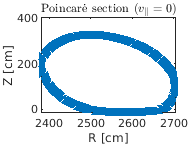

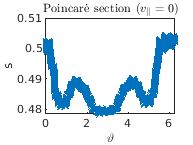

if gorilla_plot.GORILLA_PLOT_NML.boole_poincare_vpar_0 == true
    name=strsplit(gorilla_plot.GORILLA_PLOT_NML.filename_poincare_vpar_0_rphiz,'.');
    figure
    plot(data.(name{1})(:,1),data.(name{1})(:,3),'x')
    hold on
    xlabel('R [cm]')
    ylabel('Z [cm]')
    title('Poincar\.{e} section ($v_{\parallel}=0$)','Interpreter','latex');
    hold off
    savefig([path_data_plots,'/',name{1},'.fig']);
    
    name=strsplit(gorilla_plot.GORILLA_PLOT_NML.filename_poincare_vpar_0_sthetaphi,'.');
    figure
    plot(data.(name{1})(:,2),data.(name{1})(:,1),'x')
    hold on
    xlabel('\vartheta')
    ylabel('s')
    xlim([0,2*pi])
    title('Poincar\.{e} section ($v_{\parallel}=0$)','Interpreter','latex');
    hold off
    %savefig([path_data_plots,'/',name{1},'.fig']);
    saveas(gcf,[path_data_plots,'/',name{1},'.png']);
end

3D plot in cartesian coordinates

if gorilla_plot.GORILLA_PLOT_NML.boole_full_orbit == true
    name=strsplit(gorilla_plot.GORILLA_PLOT_NML.filename_full_orbit_rphiz,'.');
    figure
    plot3(data.(name{1})(:,1).*cos(data.(name{1})(:,2)),data.(name{1})(:,1).*sin(data.(name{1})(:,2)),data.(name{1})(:,3),'x')
    hold on
    xlabel('x [cm]')
    ylabel('y [cm]')
    zlabel('z [cm]')
    title('3D orbit','Interpreter','latex');
    hold off
    %savefig([path_data_plots,'/',name{1},'.fig']);
    saveas(gcf,[path_data_plots,'/',name{1},'.png']);
end

Plot for the normalized total energy

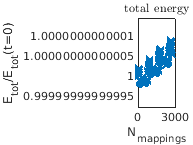

if gorilla_plot.GORILLA_PLOT_NML.boole_e_tot == true
   name=strsplit(gorilla_plot.GORILLA_PLOT_NML.filename_e_tot,'.');
   data.(name{1})(:,2)=data.(name{1})(:,2)./data.(name{1})(1,2);
   plot(abs(data.(name{1})(:,1)),data.(name{1})(:,2),'x')
   hold on
   xlabel('N_{mappings}')
   ylabel('E_{tot}/E_{tot}(t=0)')
   title('total energy','Interpreter','latex');
   hold off
   %savefig([path_data_plots,'/',name{1},'.fig']);
   saveas(gcf,[path_data_plots,'/',name{1},'.png']);
end

Plot for the normalized toroidal angular momentum

if gorilla_plot.GORILLA_PLOT_NML.boole_p_phi == true
   name=strsplit(gorilla_plot.GORILLA_PLOT_NML.filename_p_phi,'.');
   data.(name{1})(:,2)=data.(name{1})(:,2)./data.(name{1})(1,2);
   plot(abs(data.(name{1})(:,1)),data.(name{1})(:,2),'x')
   hold on
   xlabel('N_{mappings}')
   ylabel('$p_{\varphi}/p_{\varphi}(t=0)$','Interpreter','latex')
   title('toroidal angular momentum','Interpreter','latex');
   hold off
   %savefig([path_data_plots,'/',name{1},'.fig']);
   saveas(gcf,[path_data_plots,'/',name{1},'.png']);
end

Plot for the normalized parallel adiabatic invariant

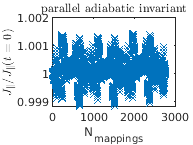

if gorilla_plot.GORILLA_PLOT_NML.boole_J_par == true
   name=strsplit(gorilla_plot.GORILLA_PLOT_NML.filename_J_par,'.');
   data.(name{1})(:,2)=data.(name{1})(:,2)./data.(name{1})(1,2);
   plot(abs(data.(name{1})(:,1)),data.(name{1})(:,2),'x')
   hold on
   xlabel('N_{mappings}')
   ylabel('$J_{\parallel}/J_{\parallel}(t=0)$','Interpreter','latex')
   title('parallel adiabatic invariant','Interpreter','latex');
   hold off
   %savefig([path_data_plots,'/',name{1},'.fig']);
   saveas(gcf,[path_data_plots,'/',name{1},'.png']);
end